# NB-IoT simulation

## ofdm parameters

clear
numSC=12;%number subcarriers, nbiot=12
numSym=42;%number ofdm symbols, nbiot=grouped 7 per frame but more for this sim
SCS=15e3;%subcarrier spacing, nbiot=15kHz


## simulation parameters

dataLength=numSC*numSym*2;
randomData=true;
nLoops=1;
filtersOn=false;
plotSpec=false;
maxSNR=25;
dopplerShift=0e3;%doppler shift geeft problemen in code!

## transmission


%base message
if randomData
    messageBits= randi([0 1],dataLength,1)
else
    messageBits=ones(dataLength,1)
end

messageBits =      0
     1
     1
     0
     1
     1
     1
     0
     0
     0



%map bits to qpsk symbols
messageInts=bit2int(messageBits,2)% grouped by 2 bits, converted to dec

messageInts =      1
     2
     3
     2
     0
     0
     1
     1
     3
     1


symbolMap=[1+1i, -1+1i, 1-1i, -1-1i] / sqrt(2); %normalized QPSK constellation points
messageSymbols = zeros(size(messageInts, 1), 1);
for k = 1:size(messageInts, 1)
    idx = messageInts(k) + 1; %map index
    messageSymbols(k) = symbolMap(idx); %symbolmap
end
messageSymbols

messageSymbols =   -0.7071 + 0.7071i
   0.7071 - 0.7071i
  -0.7071 - 0.7071i
   0.7071 - 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
  -0.7071 + 0.7071i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -0.7071 + 0.7071i


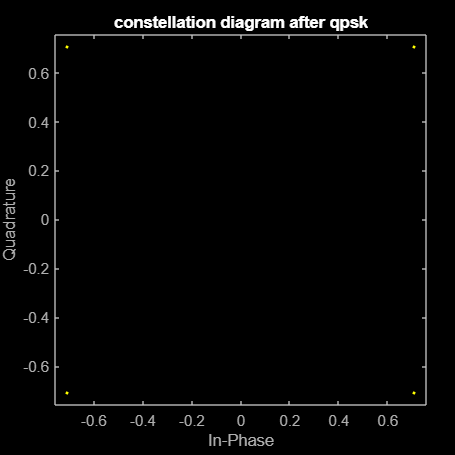

%plot scatterplot
figure;
scatterplot(messageSymbols);
title('constellation diagram after qpsk');

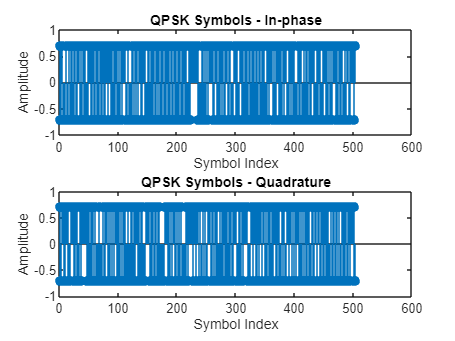


%plot time domain
figure;
subplot(2,1,1);
stem(real(messageSymbols), 'filled');
title('QPSK Symbols - In-phase');
xlabel('Symbol Index');
ylabel('Amplitude');
subplot(2,1,2);
stem(imag(messageSymbols), 'filled');
title('QPSK Symbols - Quadrature');
xlabel('Symbol Index');
ylabel('Amplitude');

% %ofdm
% % PARALLEL TO SERIAL STAP LOOPT FOUT
% numSC=12;% # subcarriers
% cpLen=3;%cyclic prefix length
% numSym=7;% # ofdm symbols
% bandwidth=180e3;
% SCS=15e3;
% carrierFreq=890e6;
% 
% numSymbolsRequired = numSC * numSym;
% if length(messageSymbols) < numSymbolsRequired
%     error('Not enough symbols to fill the OFDM frame');
% end
% 
% ofdmSymbolsMatrix = reshape(messageSymbols(1:numSymbolsRequired), numSC, numSym);%reshape into 12 carrier x7 symbols frame in freq domain
% 
% timeDomainSymbols = ifft(ofdmSymbolsMatrix, numSC);%time domain frame, 12 samples
% 
% cpSymbols = [timeDomainSymbols(end-cpLen+1:end, :); timeDomainSymbols];
% 
% txSignalOFDMA = cpSymbols(:);% (:) reshapes matrix into column
% 
% 
% 
% figure
% scatterplot(txSignalOFDMA)
% title('constellation diagram after OFDM');
% 
% % Plot the time domain signal
% figure;
% subplot(2,1,1);
% plot(real(txSignalOFDMA));
% title('OFDM Signal Time Domain');
% xlabel('Sample Index');
% ylabel('Amplitude');
% 
% [pxx,f] = pspectrum(txSignalOFDMA);
% subplot(2,1,2);
% plot(f,pow2db(pxx))
% grid on
% title('OFDM Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')


% numSC=12;% # subcarriers
% numSym=21;% # ofdm symbols
% SCS=15e3;
BW=SCS*numSC;
samplingRate = numSC * SCS;
symbolDuration = 1 / SCS; % Duration of one OFDM symbol (T=1/FS = 1/SCS)
SPS = round(samplingRate * symbolDuration);
% t = (0:SPS-1) / samplingRate; %time vector

ofdmSignal = zeros(1, numSym * SPS);
cpLen=round(SPS/4);%cyclic prefix length
t=(symbolDuration/(SPS+cpLen):symbolDuration/(SPS+cpLen):(symbolDuration)*numSym);%time for each sample


ofdmMatrix = zeros(numSC,numSym);%12x7 in nbiot
for symbolIdx =1:numSym
    ofdmMatrix(:,symbolIdx)=messageSymbols((symbolIdx-1)*numSC+1:numSC*symbolIdx);
end
ofdmMatrix%every column represents 12 carriers for 1 ofdm symbol

ofdmMatrix =   -0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i
   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.707

%the entire column/symbol is transmitted at once at different freq

timeDomainSymbolMatrix = ifft(ofdmMatrix, numSC);%time domain frame, 12 samples per symbol
%every colum contains the sample of the symbol over time, the column
%elements are transmitted one by one
cp=timeDomainSymbolMatrix(end-(cpLen-1):end,:)

cp =    0.1179 + 0.1179i   0.0000 + 0.1179i   0.1179 - 0.2357i   0.2357 + 0.0000i   0.1179 - 0.2357i   0.0000 + 0.0000i   0.0000 - 0.1179i  -0.3536 - 0.2357i   0.1179 + 0.1179i   0.3536 + 0.2357i  -0.1179 - 0.4714i  -0.1179 + 0.2357i   0.1179 + 0.0000i   0.1179 + 0.2357i  -0.1179 - 0.2357i  -0.1179 + 0.2357i  -0.2357 + 0.0000i   0.0000 - 0.1179i   0.2357 + 0.0000i   0.0000 - 0.1179i   0.1179 + 0.4714i   0.0000 + 0.1179i   0.0000 + 0.1179i  -0.1179 + 0.3536i  -0.3536 + 0.0000i   0.0000 + 0.0000i   0.2357 + 0.0000i   0.0000 - 0.1179i  -0.1179 - 0.3536i  -0.2357 + 0.0000i  -0.1179 - 0.3536i  -0.2357 - 0.1179i   0.0000 - 0.1179i   0.0000 + 0.1179i   0.0000 - 0.1179i  -0.1179 + 0.0000i   0.1179 + 0.2357i  -0.1179 + 0.2357i  -0.2357 + 0.1179i   0.0000 + 0.1179i   0.1179 + 0.0000i   0.2357 + 0.0000i
  -0.2041 + 0.4398i  -0.0158 - 0.0589i  -0.3809 - 0.3062i   0.2199 - 0.0589i  -0.0905 - 0.1021i   0.0863 + 0.4398i  -0.0316 - 0.3220i  -0.1021 - 0.0589i   0.2630 - 0.1021i  -0.1336 - 0.1452i  -0.2

timeDomainSymbolMatrix=[cp; timeDomainSymbolMatrix]%add cp

timeDomainSymbolMatrix =    0.1179 + 0.1179i   0.0000 + 0.1179i   0.1179 - 0.2357i   0.2357 + 0.0000i   0.1179 - 0.2357i   0.0000 + 0.0000i   0.0000 - 0.1179i  -0.3536 - 0.2357i   0.1179 + 0.1179i   0.3536 + 0.2357i  -0.1179 - 0.4714i  -0.1179 + 0.2357i   0.1179 + 0.0000i   0.1179 + 0.2357i  -0.1179 - 0.2357i  -0.1179 + 0.2357i  -0.2357 + 0.0000i   0.0000 - 0.1179i   0.2357 + 0.0000i   0.0000 - 0.1179i   0.1179 + 0.4714i   0.0000 + 0.1179i   0.0000 + 0.1179i  -0.1179 + 0.3536i  -0.3536 + 0.0000i   0.0000 + 0.0000i   0.2357 + 0.0000i   0.0000 - 0.1179i  -0.1179 - 0.3536i  -0.2357 + 0.0000i  -0.1179 - 0.3536i  -0.2357 - 0.1179i   0.0000 - 0.1179i   0.0000 + 0.1179i   0.0000 - 0.1179i  -0.1179 + 0.0000i   0.1179 + 0.2357i  -0.1179 + 0.2357i  -0.2357 + 0.1179i   0.0000 + 0.1179i   0.1179 + 0.0000i   0.2357 + 0.0000i
  -0.2041 + 0.4398i  -0.0158 - 0.0589i  -0.3809 - 0.3062i   0.2199 - 0.0589i  -0.0905 - 0.1021i   0.0863 + 0.4398i  -0.0316 - 0.3220i  -0.1021 - 0.0589i   0.2630 - 0.1021i  -0.


timeDomainSymbols=reshape (timeDomainSymbolMatrix,[],1)

timeDomainSymbols =    0.1179 + 0.1179i
  -0.2041 + 0.4398i
  -0.0316 - 0.4398i
  -0.1179 + 0.1179i
   0.1179 + 0.1179i
   0.2041 + 0.0316i
   0.1179 + 0.1179i
  -0.1179 + 0.1179i
   0.1179 + 0.1179i
  -0.3536 - 0.1179i


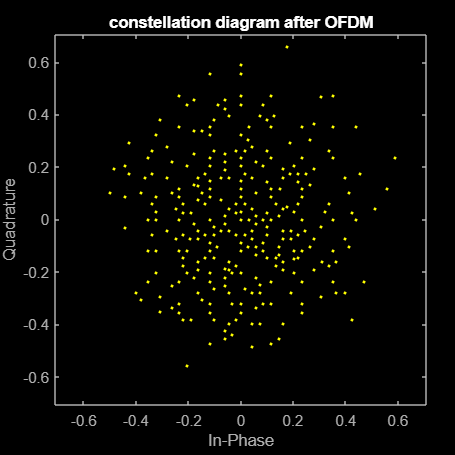

% plot ofdm signal

if plotSpec 
figure
window=hamming(7);
spectrogram(timeDomainSymbols,window,round(length(window)/2),BW)
end

figure
scatterplot(timeDomainSymbols)
title('constellation diagram after OFDM');

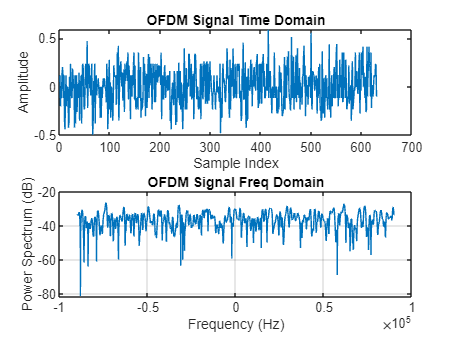


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(timeDomainSymbols));
title('OFDM Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(timeDomainSymbols,samplingRate);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('OFDM Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

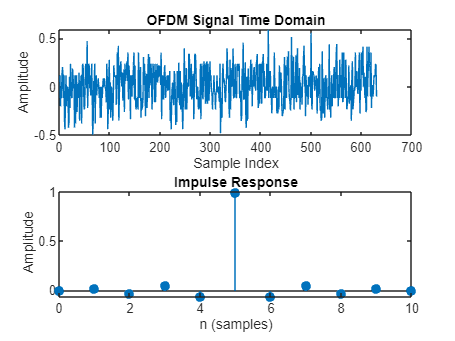

%upsampling
L = 1;  % Upsampling factor
rolloff = 0.25;  % Roll-off factor for the RRC filter
span = 10;  % Filter span in symbols

txSignalUpsampled = upsample(timeDomainSymbols, L);

rrcFilter = rcosdesign(rolloff, span, L);
impz(rrcFilter)

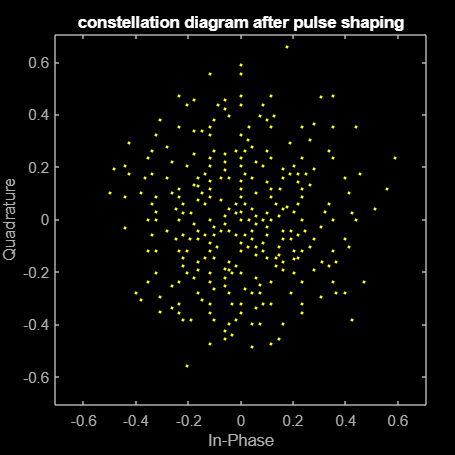

if filtersOn
    txSignalShaped = conv(txSignalUpsampled, rrcFilter, 'same');
else
    txSignalShaped = txSignalUpsampled;

end

figure
scatterplot(txSignalShaped)
title('constellation diagram after pulse shaping');


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(txSignalShaped));
title('pulse shaped Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(txSignalShaped,samplingRate);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('pulse shaped Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

% %convert to 900 MHz
% Fc=900e6;
% Fs=2*180e3;
% t = (0:length(txSignalShaped)-1)' / Fs; % Time vector
% cosCarrier = cos(2 * pi * Fc * t);
% sinCarrier = sin(2 * pi * Fc * t);
% txPassband = real(txSignalShaped) .* cosCarrier - imag(txSignalShaped) .* sinCarrier;
% % Plot the time domain signal after upconversion
% figure;
% plot(t(1:length(txPassband)), txPassband); % Plot a segment for better visualization
% title('Passband Signal - Time Domain');
% xlabel('Time (s)');
% ylabel('Amplitude');
% %freq
% [pxx,f] = pspectrum(txSignalShaped,Fs);
% subplot(2,1,2);
% plot(f+Fc,pow2db(pxx))
% grid on
% title('pulse shaped Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')

## channel

een vaste doppler shift zal in deze simulatie geen verschil maken, heel het signaal verschuift in freq domein maar uiteindelijk wordt de 180 kHz toch in 12 carriers opgesplitst,

varierende doppler shift zal wss wel effect hebben?

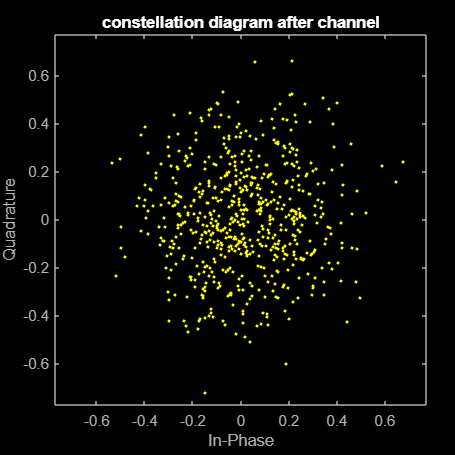

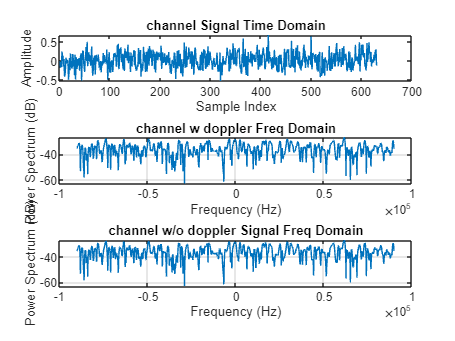

for counter=1:nLoops
%check filters, error rate is te hoog?

dopplerEffect = exp(1i * 2 * pi * dopplerShift * t);
txSignalDopplerShifted = transpose(txSignalUpsampled) .* (dopplerEffect);

SNR=20-(nLoops-counter);
% rxSignal=awgn(txSignalShaped,SNR);


rxSignal=awgn(txSignalDopplerShifted,SNR);
rxSignal2=awgn(txSignalUpsampled,SNR);
% rxSignal=txSignalShaped;

if counter==nLoops %only plot in last loop
    % Plot the time domain signal after channel
    figure
    scatterplot(rxSignal)
    title('constellation diagram after channel');
    
    % Plot the time domain signal
    figure;
    subplot(3,1,1);
    plot(real(rxSignal));
    title('channel Signal Time Domain');
    xlabel('Sample Index');
    ylabel('Amplitude');
    
    [pxx,f] = pspectrum(rxSignal,samplingRate);
    subplot(3,1,2);
    plot(f,pow2db(pxx))
    grid on
    title('channel w doppler Freq Domain');
    xlabel('Frequency (Hz)')
    ylabel('Power Spectrum (dB)')

    [pxx,f] = pspectrum(rxSignal,samplingRate);
    subplot(3,1,3);
    plot(f,pow2db(pxx))
    grid on
    title('channel w/o doppler Signal Freq Domain');
    xlabel('Frequency (Hz)')
    ylabel('Power Spectrum (dB)')
end

## receiver

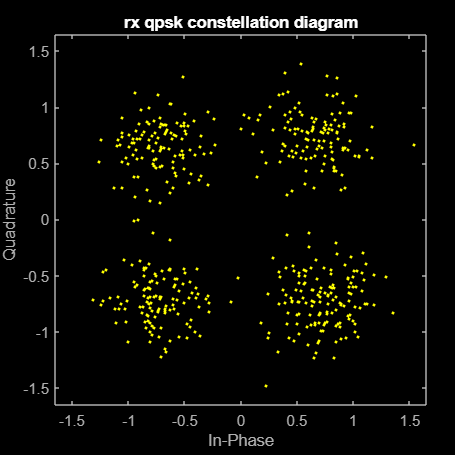

% %downconvert to baseband
% I_component = rxSignal .* cosCarrier;
% Q_component = rxSignal .* sinCarrier;
% 
% filterOrder = 64;
% cutoffFreq = Fc / (2 * Fs); % Normalized cutoff frequency
% lpFilt = designfilt('lowpassfir', 'FilterOrder', filterOrder, 'CutoffFrequency', 0.5);
% 
% I_baseband = filtfilt(lpFilt, I_component);
% Q_baseband = filtfilt(lpFilt, Q_component);
% 
% rxBaseband = I_baseband - 1i * Q_baseband;

%matched filter
if filtersOn
    matchedFilter = rcosdesign(rolloff, span, L);
    rxSignalFiltered = conv(rxSignal, matchedFilter, 'same');
else
    rxSignalFiltered = rxSignal;

end

rxSignalFiltered;

%downsample
% rxSignalDownsampled = downsample(rxSignalFiltered, L);
if counter==nLoops
    figure;
    scatterplot(rxSignalFiltered);
    title('rx filtered constellation diagram');
end

%cp
% rxSymbolsWithCP = reshape(rxSignalFiltered, [], numSym);
rxSymbolsWithCP = reshape(rxSignal, [], numSym);
%rxSymbolsWithCP
rxSymbols = rxSymbolsWithCP(cpLen+1:end, :);%remove cp from top of matrix (cplen +2 because matlab takes from the next sample to the end)
%fft
rxSymbolsFreq = fft(rxSymbols, numSC);% fft to freq domain
%qpsk
rxQPSKSymbols = rxSymbolsFreq(:);
demodulatedBits = zeros(length(rxQPSKSymbols)*2, 1);

if counter==nLoops
    figure;
    scatterplot(rxQPSKSymbols);
    title('rx qpsk constellation diagram');
end


% Demodulate QPSK symbols to bits
for k = 1:length(rxQPSKSymbols)
    [~, idx] = min(abs(rxQPSKSymbols(k) - symbolMap));
    demodulatedBits(2*k-1:2*k) = de2bi(idx-1, 2, 'left-msb');
end

errors=sum(transpose(demodulatedBits)~=transpose(messageBits(1:dataLength)));
nbiot_ber(counter)=errors/dataLength;

symbolRate=samplingRate/SPS;
bitRate =  2*12*symbolRate;

SNR_linear = 10^(SNR / 10);
%Eb_N0(counter) = (SNR_linear * samplingRate) / bitRate

EbN0_sim(counter)=10*log10(SNR_linear*samplingRate/bitRate);


end
nbiot_ber
EbN0_sim

nbiot_ber = 0.0050

EbN0_sim = 16.9897

## ber

[https://nl.mathworks.com/help/releases/R2023a/comm/ug/analytical-expressions-used-in-berawgn-function-and-bit-error-rate-analysis-app.html](https://nl.mathworks.com/help/releases/R2023a/comm/ug/analytical-expressions-used-in-berawgn-function-and-bit-error-rate-analysis-app.html)

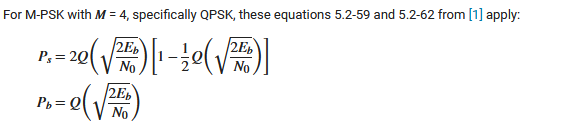

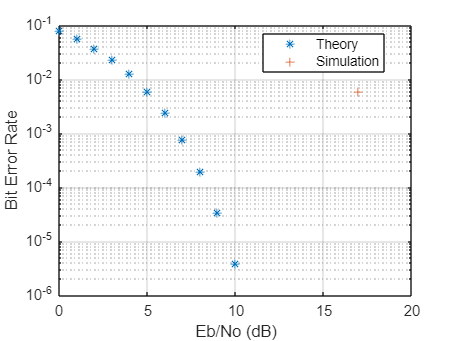


EbN0=(0:10);
ber=berawgn(EbN0,"psk",4,"nondiff");
figure
semilogy(transpose(EbN0),ber,'*')
hold on
semilogy(transpose(EbN0_sim),nbiot_ber,'+')
legend({'Theory','Simulation'},'Location','best')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
grid on